%1
T = import_airborne_gravity_data('Data/Q1/RESOURCES/NGS_GRAVD_Block_CN03_BETA1/NGS_GRAVD_Block_CN03_Gravity_Data_BETA1.txt')

T = 	1.0e+05 *

    0.0004   -0.0010    9.7849    0.0636
    0.0004   -0.0010    9.7849    0.0636
    0.0004   -0.0010    9.7849    0.0636
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637



latitude = T(:,1);
longitude = T(:,2);
elipsoidal_height = T(:,4);
gravity_filtered = T(:,3);
Ellipsoid = make_Ellipsoid('WGS84')

Ellipsoid = struct with fields:
              GM: 3.9860e+14
           omega: 7.2921e-05
    gammaEquator: 9.7803e+05
       gammaPole: 9.8322e+05
               a: 6378137
               b: 6.3568e+06
               e: 0.0818
              e2: 0.0067
               f: 0.0034


open('Data/Q2/Downloaded_Data/GGM02C.gdf')

%2 
%N_ggm = open('/Users/sunilbhavsar/Documents/CE678_PROJECT/Q2/RESOURCES/AIUB-CHAMP01S_a50de3dfc2ab0cdb9a2ae28b113f3398304202075281a813ba9cc27562a667af.gdf')
%a = open('/Users/sunilbhavsar/Documents/CE678_PROJECT/AIUB-CHAMP01S_a50de3dfc2ab0cdb9a2ae28b113f3398304202075281a813ba9cc27562a667af.gdf')
nggm = import_geoid_heights('Data/Q2/Downloaded_Data/GGM02C.gdf',latitude,longitude)

nggm =   -25.4579
  -25.4563
  -25.4547
  -25.4532
  -25.4516
  -25.4501
  -25.4485
  -25.4470
  -25.4455
  -25.4440


%adding 
orthometric_height = calc_orthometric_height(elipsoidal_height,nggm)

orthometric_height = 	1.0e+03 *

    6.3388
    6.3391
    6.3395
    6.3399
    6.3404
    6.3408
    6.3412
    6.3413
    6.3414
    6.3413


%3
Ellipsoid = make_Ellipsoid('WGS84');
free_air_anomily = gravity_filtered + calc_FAC(latitude,Ellipsoid,orthometric_height)-calc_gnorm_ellip_surface(latitude,Ellipsoid)

free_air_anomily = 	1.0e+03 *

   -3.8995
   -3.8996
   -3.8997
   -3.8999
   -3.9001
   -3.9003
   -3.9004
   -3.9005
   -3.9005
   -3.9005


%4

del_g_ggm = import_grav_anomaly('Data/Q4/GGM02C_Anomily.gdf',latitude,longitude)

del_g_ggm =    15.8541
   15.8520
   15.8484
   15.8451
   15.8418
   15.8385
   15.8352
   15.8316
   15.8258
   15.8204


del_g_s_and_mw = free_air_anomily-del_g_ggm;

%5
g_atm_and_s_mw = remove_g_atm(del_g_s_and_mw,orthometric_height)

g_atm_and_s_mw = 	1.0e+03 *

   -3.9157
   -3.9158
   -3.9160
   -3.9162
   -3.9163
   -3.9165
   -3.9166
   -3.9167
   -3.9167
   -3.9168


%6
lat = min(latitude):0.01:max(latitude);
long = min(longitude):0.01:max(longitude);
[Latitude_grid,Longitude_grid] = meshgrid(lat,long);

%7
files = ['Data/Q7/srtm_16_04/srtm_16_04.asc';'Data/Q7/srtm_17_04/srtm_17_04.asc'];
size(files)

ans =      2    33



H = combine_DEM_data(files,Latitude_grid,Longitude_grid);

minlon = -105

minlat = 40

minlon = -100

minlat = 40

tc = terrain_correction_fft(H,lat,long,0.01);

Padding array
Determining spatial grids
Setting up integration kernel
FFT kernel for TC
FFT H^2
FFT H
FFT ones
Computing TC


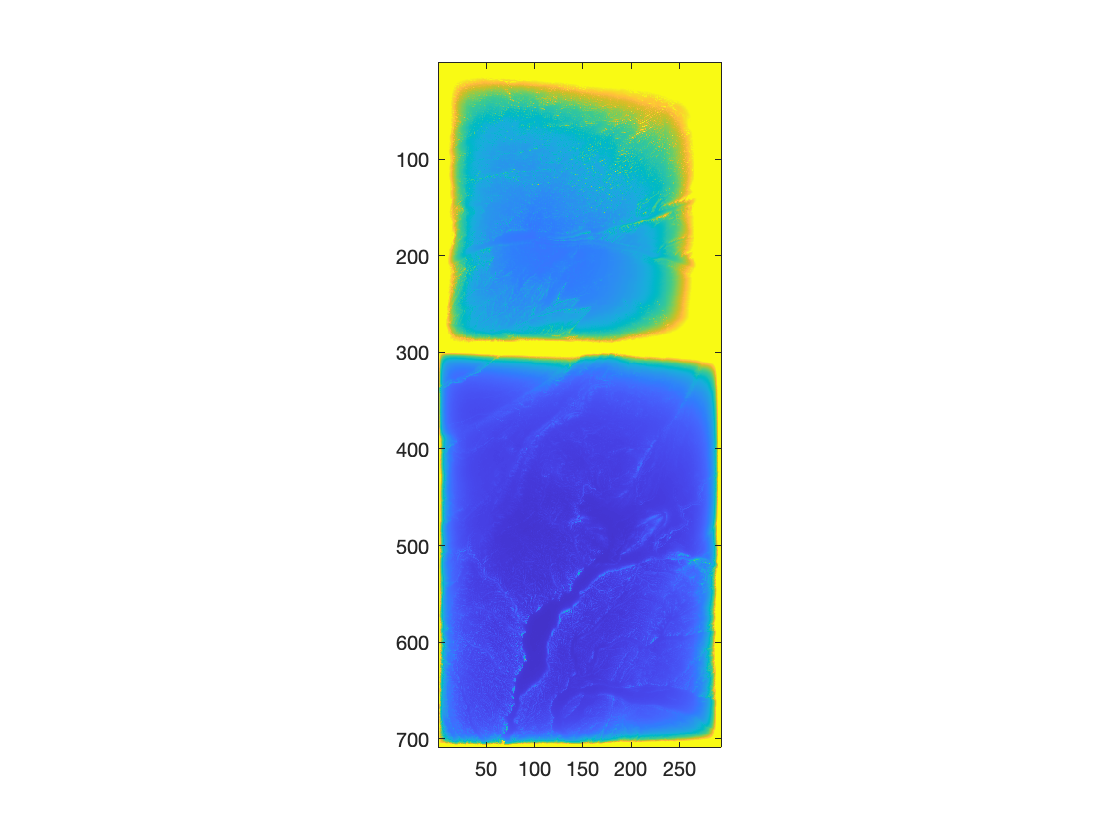

imagesc(tc)
axis image
caxis([0 1])

gfaye = calc_gfaye(g_atm_and_s_mw,longitude,latitude,tc,Latitude_grid,Longitude_grid);


%8
%and 9

Tr = calc_disturb_potential(H,Latitude_grid,Longitude_grid,gfaye);
Nr = calc_undulation(Tr,Latitude_grid,Ellipsoid);


%10
N_co_geoid = calc_n_cogeoid(Nr,nggm,latitude,longitude,Latitude_grid,Longitude_grid);



%11
 R = Ellipsoid.a

R = 6378137

 G = 6.67*10^-6

G = 6.6700e-06

 rho = 2670

rho = 2670

 gamma = calc_gnorm_ellip_surface(Latitude_grid,Ellipsoid);
 Xm=Longitude_grid*111319.9*cosd(mean(mean(Latitude_grid)));
 Ym=Latitude_grid*111319.9;
 rq=1./sqrt((Xm-mean(mean(Xm))).^2+(Ym-mean(mean(Ym))).^2);
 deltaN_indirect_term1 = pi*H.^2

deltaN_indirect_term1 = 	1.0e+06 *

    1.8003    1.8482    1.8578    1.8578    1.8050    1.8530    1.8869    1.8869    1.9261    1.8772    1.9064    1.9261    1.9113    1.8821    1.9458    1.9016    1.8723    1.9458    1.9359    1.9064    1.8627    1.8482    1.9064    1.9212    1.9310    1.9607    2.0006    2.0409    2.0510    2.0510    2.0663    2.0358    2.0663    2.1021    2.1176    2.0867    2.1227    2.1176    2.1124    2.1176    2.1021    2.0970    2.1331    2.1956    2.2326    2.2379    2.2698    2.2062    2.2485    2.2698
    1.8433    1.8675    1.8869    1.8482    1.7908    1.8723    1.8869    1.9016    1.9064    1.9261    1.9261    1.9557    1.9607    1.9458    1.9956    1.9261    1.9261    1.9458    1.9756    1.9409    1.9162    1.8723    1.9016    1.9310    1.9806    2.0006    2.0006    2.0308    2.0409    2.0257    2.0510    1.9956    2.0460    2.0970    2.0561    2.0867    2.1538    2.0816    2.1073    2.0207    2.1227    2.1434    2.2167    2.2751    2.1538    2.2432   

 deltaN_indirect_term2 = ifft2(fft2(H.^3).*fft2(rq.^3))

deltaN_indirect_term2 = 	1.0e+33 *

    0.6761    0.6416    0.6416    0.6116    0.5921    0.5825    0.5921    0.5544    0.5272    0.5452    0.5096    0.4980    0.4700    0.4700    0.4867    0.5009    0.4952    0.4783    0.4839    0.4645    0.4617    0.4509    0.4783    0.5009    0.4980    0.4617    0.4456    0.4324    0.4221    0.4247    0.4430    0.4351    0.4170    0.4145    0.4145    0.4145    0.4119    0.4247    0.4483    0.4403    0.4377    0.4430    0.4430    0.4923    0.4672    0.4727    0.5009    0.5009    0.4923    0.5154
    0.6450    0.5699    0.6315    0.5889    0.5668    0.5606    0.5889    0.5606    0.5362    0.4980    0.5213    0.5067    0.4923    0.4617    0.4755    0.5009    0.4952    0.4923    0.4980    0.4727    0.4617    0.4483    0.4509    0.4563    0.4590    0.4755    0.4536    0.4298    0.4170    0.4196    0.4247    0.4324    0.4403    0.4069    0.4145    0.4247    0.4069    0.4324    0.4536    0.4403    0.4645    0.4811    0.4755    0.4923    0.4867    0.5183   

 deltaN_indirect_term3 = - H.^3.*conv2(1,1./rq.^3,'same')

deltaN_indirect_term3 = 	1.0e+-15 *

   -0.1239   -0.1289   -0.1299   -0.1299   -0.1244   -0.1294   -0.1329   -0.1329   -0.1371   -0.1319   -0.1350   -0.1371   -0.1355   -0.1324   -0.1392   -0.1345   -0.1314   -0.1392   -0.1382   -0.1350   -0.1304   -0.1289   -0.1350   -0.1366   -0.1376   -0.1408   -0.1451   -0.1495   -0.1507   -0.1507   -0.1523   -0.1490   -0.1523   -0.1563   -0.1580   -0.1546   -0.1586   -0.1580   -0.1575   -0.1580   -0.1563   -0.1557   -0.1598   -0.1669   -0.1711   -0.1717   -0.1754   -0.1681   -0.1729   -0.1754
   -0.1284   -0.1309   -0.1329   -0.1289   -0.1229   -0.1314   -0.1329   -0.1345   -0.1350   -0.1371   -0.1371   -0.1403   -0.1408   -0.1392   -0.1446   -0.1371   -0.1371   -0.1392   -0.1424   -0.1387   -0.1361   -0.1314   -0.1345   -0.1376   -0.1430   -0.1451   -0.1451   -0.1484   -0.1495   -0.1479   -0.1507   -0.1446   -0.1501   -0.1557   -0.1512   -0.1546   -0.1621   -0.1540   -0.1569   -0.1473   -0.1586   -0.1610   -0.1693   -0.1760   -0.1621   -0.1723  

 deltaN_indirect_term4 =  + 3*R^2/40 .*conv2(H.^5,1./rq.^5,'same')

deltaN_indirect_term4 = 	1.0e+59 *

    0.2541    0.2568    0.2595    0.2623    0.2651    0.2679    0.2708    0.2736    0.2765    0.2795    0.2824    0.2853    0.2883    0.2913    0.2943    0.2974    0.3004    0.3035    0.3065    0.3096    0.3127    0.3159    0.3191    0.3223    0.3255    0.3288    0.3321    0.3354    0.3388    0.3421    0.3455    0.3489    0.3524    0.3558    0.3593    0.3628    0.3663    0.3699    0.3735    0.3771    0.3808    0.3844    0.3881    0.3919    0.3957    0.3995    0.4034    0.4074    0.4114    0.4155
    0.2507    0.2533    0.2560    0.2587    0.2615    0.2643    0.2671    0.2699    0.2727    0.2756    0.2785    0.2814    0.2843    0.2873    0.2903    0.2933    0.2963    0.2993    0.3023    0.3053    0.3084    0.3115    0.3146    0.3178    0.3210    0.3242    0.3275    0.3308    0.3341    0.3374    0.3407    0.3440    0.3474    0.3509    0.3543    0.3577    0.3612    0.3647    0.3682    0.3718    0.3754    0.3790    0.3827    0.3863    0.3901    0.3939   

 deltaN_indirect_term5 = - H.^5.*conv2(1,1./rq.^5,'same')

deltaN_indirect_term5 = 	1.0e+-25 *

   -0.0308   -0.0329   -0.0333   -0.0333   -0.0310   -0.0331   -0.0346   -0.0346   -0.0365   -0.0342   -0.0355   -0.0365   -0.0358   -0.0344   -0.0374   -0.0353   -0.0340   -0.0374   -0.0369   -0.0355   -0.0335   -0.0329   -0.0355   -0.0362   -0.0367   -0.0381   -0.0401   -0.0421   -0.0427   -0.0427   -0.0435   -0.0419   -0.0435   -0.0454   -0.0462   -0.0445   -0.0465   -0.0462   -0.0459   -0.0462   -0.0454   -0.0451   -0.0471   -0.0506   -0.0527   -0.0530   -0.0550   -0.0512   -0.0537   -0.0550
   -0.0327   -0.0337   -0.0346   -0.0329   -0.0304   -0.0340   -0.0346   -0.0353   -0.0355   -0.0365   -0.0365   -0.0379   -0.0381   -0.0374   -0.0398   -0.0365   -0.0365   -0.0374   -0.0388   -0.0372   -0.0360   -0.0340   -0.0353   -0.0367   -0.0391   -0.0401   -0.0401   -0.0416   -0.0421   -0.0414   -0.0427   -0.0398   -0.0424   -0.0451   -0.0429   -0.0445   -0.0482   -0.0443   -0.0456   -0.0411   -0.0465   -0.0476   -0.0518   -0.0553   -0.0482   -0.0534  

 deltaN_indirect = -(G*rho./gamma).*(deltaN_indirect_term1+deltaN_indirect_term2 +deltaN_indirect_term3+deltaN_indirect_term4+deltaN_indirect_term5)

deltaN_indirect = 	1.0e+51 *

   -0.4618   -0.4666   -0.4715   -0.4765   -0.4817   -0.4868   -0.4920   -0.4972   -0.5024   -0.5077   -0.5130   -0.5184   -0.5238   -0.5292   -0.5347   -0.5403   -0.5458   -0.5514   -0.5570   -0.5625   -0.5681   -0.5739   -0.5797   -0.5856   -0.5915   -0.5974   -0.6034   -0.6095   -0.6155   -0.6216   -0.6277   -0.6339   -0.6402   -0.6465   -0.6528   -0.6591   -0.6655   -0.6720   -0.6785   -0.6851   -0.6918   -0.6984   -0.7052   -0.7120   -0.7189   -0.7259   -0.7329   -0.7402   -0.7475   -0.7549
   -0.4554   -0.4602   -0.4651   -0.4700   -0.4751   -0.4802   -0.4852   -0.4904   -0.4955   -0.5008   -0.5060   -0.5112   -0.5166   -0.5219   -0.5274   -0.5328   -0.5383   -0.5438   -0.5493   -0.5548   -0.5603   -0.5659   -0.5717   -0.5775   -0.5833   -0.5891   -0.5950   -0.6010   -0.6069   -0.6129   -0.6190   -0.6251   -0.6312   -0.6375   -0.6436   -0.6498   -0.6562   -0.6625   -0.6690   -0.6755   -0.6820   -0.6886   -0.6952   -0.7019   -0.7087   -0.7156   -0.722

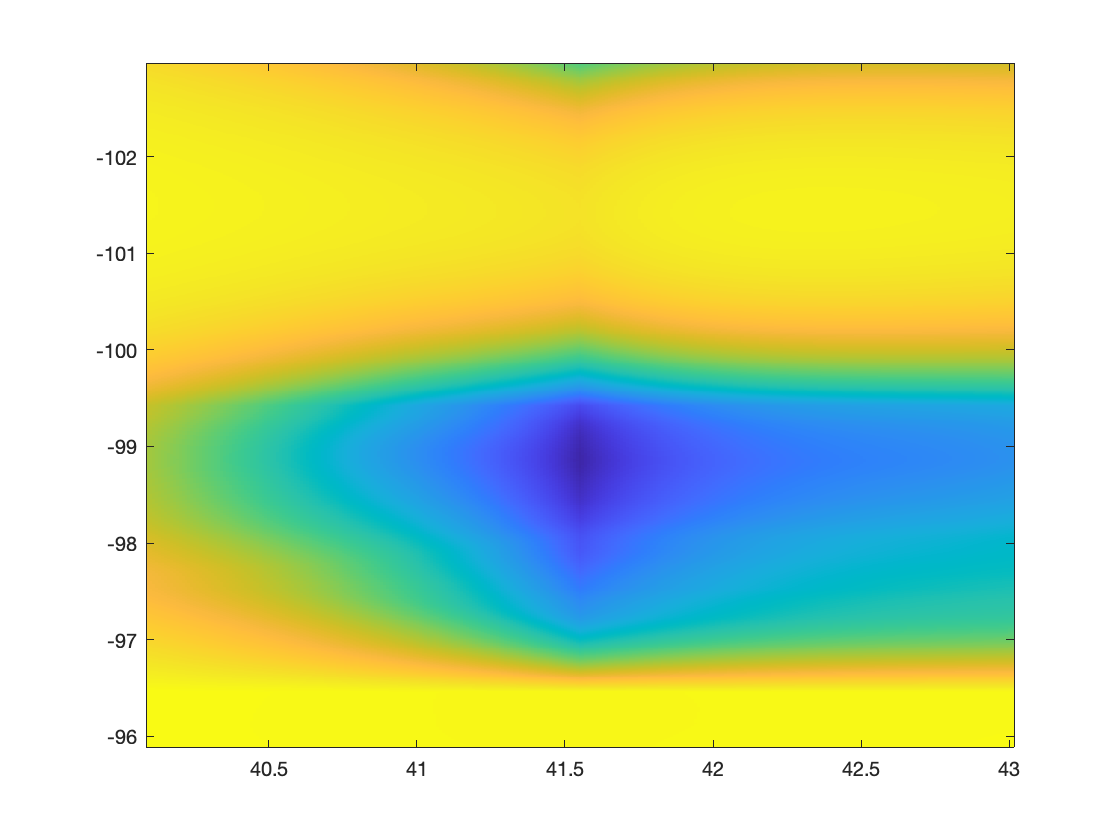

 imagesc(lat,long,deltaN_indirect)

help combine_DEM_data  

  combine_DEM_data(files,Latitude_grid,Longitude_grid) will take input DEM files
  downloaded from SRTM website and user interested Latitue and Longitude grid 
  and give final DEM height matrix mapped over Latitude and Longitude grid.
  input : 
  1 - files - array of strings - each string containg file path of DEM file 
  2 - Latitude grid (double) - Grid of latitudes of area of interest(degrees)
  3 - Longitude grid (double)- Grid of latitudes of area of interest(degrees)
  IMP - Latitude and longitude grid must have minimum resololution of 0.01
  and they must be inside or equal to the area covered by the DEM heights data.
 
  TIP - download DEM values from  here
  
  OUTPUT - 
  H - dem heights mapped over latitude and longitude grid



help import_airborne_gravity_data


function H1 = addPadding(H)
    sizeH = size(H);
  
    H1 = [H,zeros([sizeH(1) sizeH(2)-1]);zeros([sizeH(1)-1 sizeH(2)]),zeros([sizeH(1)-1 sizeH(2)-1])];
  %   H1 =  [zeroH,zeroH,zeroH;zeroH,H,zeroH;zeroH,zeroH,zeroH];
end
function H1 = addPadding_full(H)
    sizeH = size(H);
    zeroH = zeros(sizeH);
  %  H1 = [H,zeros([sizeH(1) sizeH(2)-1]);zeros([sizeH(1)-1 sizeH(2)]),zeros([sizeH(1)-1 sizeH(2)-1])];
     H1 =  [zeroH,zeroH,zeroH;zeroH,H,zeroH;zeroH,zeroH,zeroH];
end



%------------------------------------------------------
function gammas = gammas(latitude)
    a = 6378137.0;
    b = 6356752.314140;
    gamma_a = 9.7803267714;
    gamma_b = 9.8321863685;
    omega = 7292115.0*10^11;
    GM = 3986004.418*10^8 ;
    m = ((omega^2)*(a^2)*b)/GM;
    f = (a-b)/a;
    gammas = (a*gamma_a*(cosd(latitude).^2) + b*gamma_b*(sind(latitude).^2))./((a*(cosd(latitude).^2)+b*(sind(latitude).^2)).^0.5);
end